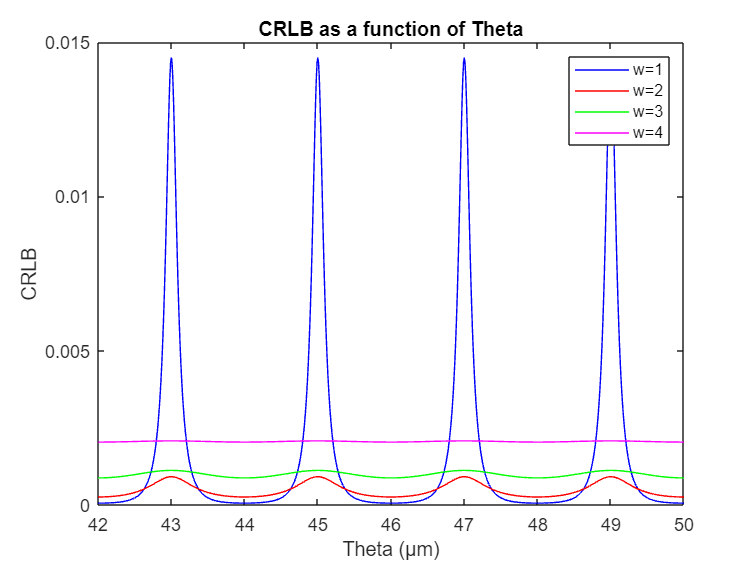

clc;


% plot the CRLB function 
a = 1;
N = 100; 
omega_w = [1,2,3,4];
omega = 2;
dx = 2;
S_b = 0.01;
S_r = omega/(2*sqrt(2*log(2))); 
S_r_w = omega_w/(2*sqrt(2*log(2))); 

Th= 42:0.01:50;

% Preallocating for better performance
aa = zeros(4, length(Th));

for i = 1:1:length(Th)
    aa(1, i) = cramerrao(Th(i), N, dx, S_r_w(1), S_b);
    aa(2, i) = cramerrao(Th(i), N, dx, S_r_w(2), S_b);
    aa(3, i) = cramerrao(Th(i), N, dx, S_r_w(3), S_b);
    aa(4, i) = cramerrao(Th(i), N, dx, S_r_w(4), S_b);
end

% Plotting the Cramer-Rao lower bound for all four arrays
figure;
plot(Th, aa(1,:), 'b', Th, aa(2,:), 'r', Th, aa(3,:), 'g', Th, aa(4,:), 'm');
legend('w=1', 'w=2', 'w=3', 'w=4');
xlabel('Th');
ylabel('Cramer-Rao Lower Bound');
title('CRLB as a function of Theta')
xlabel('Theta (μm)')
ylabel('CRLB')

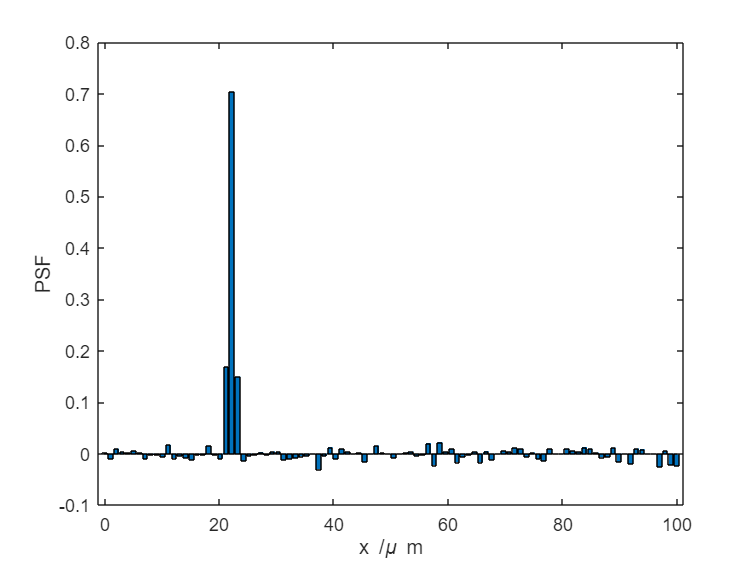


% Function calculation the  PSF
th_ref = 45;
I =linspace(0,N-1,N);
X = linspace(0,N,N);
signal_noisy = signal_generation(th_ref,omega,N,a,S_b,dx,I); % Realization of noisy signal 
bar(X,signal_noisy)
xlabel('x /\mu m')
ylabel('PSF')

PSF = Point Spread Functio

%theta = 44;
%text_likelihood = likelihood(theta,S_b,PSF,a,omega,dx);

we can use the likelihood function to extimate the \theta, we need a signal dataset s_i , and we need a estimator r_i and a log-likelihood builed by a noise b_i 

minimizer = fminsearch(@(theta) -likelihood(theta,a,S_b,signal_noisy,omega,dx), 35)

minimizer = 44.9625

Q9 In this section , we will use Monte-Carlo simulation to repeate 100 time to calculte the statistical mean and vairance of the ML estimator

mean_value = 0;
theta_ref = 40;
Nr = 100;
theta_estimate = zeros(1,Nr);
for i = 1 :1 : Nr
    Signal_noisy = signal_generation(theta_ref,omega,N,a,S_b,dx,I);
    value = fminsearch(@(theta) -likelihood(theta,a,S_b,Signal_noisy,omega,dx), 35);
    theta_estimate(i) = value;
end
mean_theta =mean(theta_estimate)

mean_theta = 40.0002

theta_variance = var(theta_estimate)

theta_variance = 3.3946e-04

Q10 We can try the different intial condition , to evaluate the estmato performance 

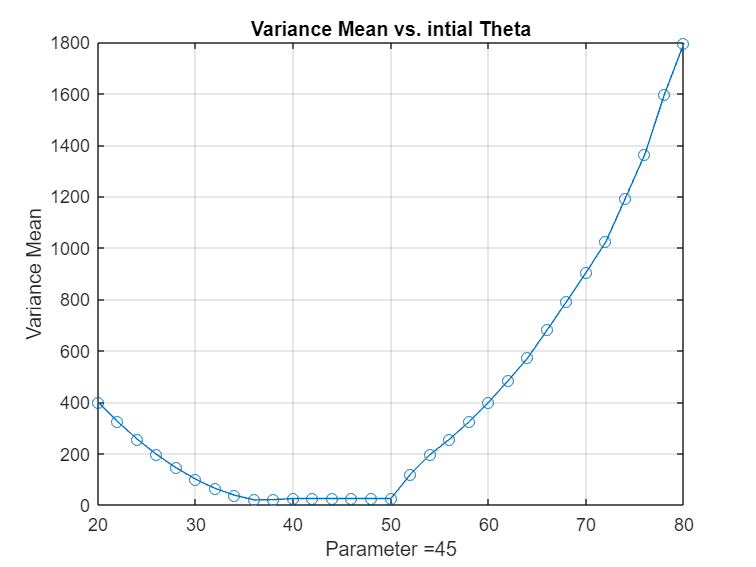

% Initialize a matrix to store the variance_mean values
theta_values = 20:2:80;
variance_mean_values = zeros(size(theta_values));

% Loop through theta values
for idx = 1:length(theta_values)
    theta = theta_values(idx);
    variance = 0;
    for i=1:1:Nr
        Signal_noisy = signal_generation(th_ref,omega,N,a,S_b,dx,I);
        val = fminsearch(@(theta) -likelihood(theta,a,S_b,Signal_noisy,omega,dx), theta);
        variance = variance + (val-mean_theta)^2;
    end
    variance_mean = variance / Nr;
    
    % Save the variance_mean value to the matrix
    variance_mean_values(idx) = variance_mean;
end

% Plot the variance_mean values
figure; % Create a new figure
plot(theta_values, variance_mean_values, '-o'); % Plot with circles at each data point
xlabel('Parameter =45');
ylabel('Variance Mean');
title('Variance Mean vs. intial Theta');
grid on;

In this section, we can build the CRLB function of w, to evlaue the variance CRLB value based on the w, to find the best w of PDF, we set the \theta as a constant

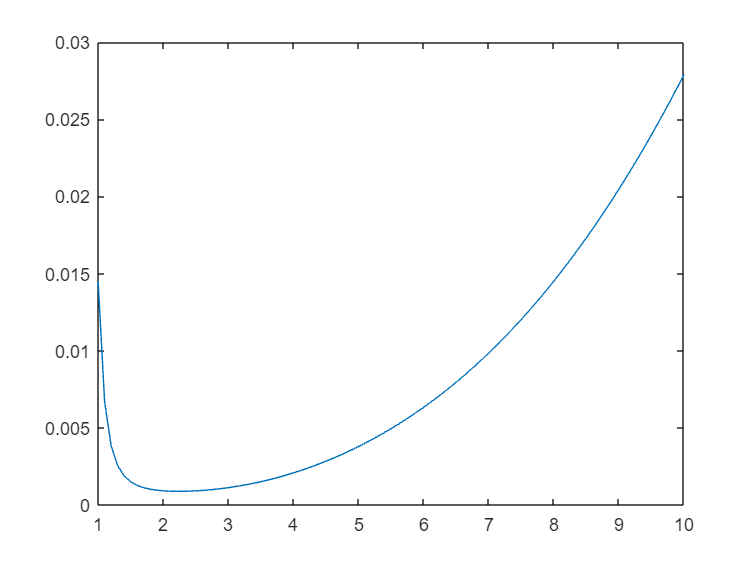

theta_value= 45;
w_values = 1:0.1:10;
CRLB_value = zeros(size(w_values));
% Loop through w values
for idx = 1:length(w_values)
    w_value = w_values(idx);
    variance = 0;
    CRLB_w = cramerrao_w(theta_value, N, dx,w_value,S_b);
    CRLB_value(idx) = CRLB_w;
end
plot(w_values,CRLB_value)

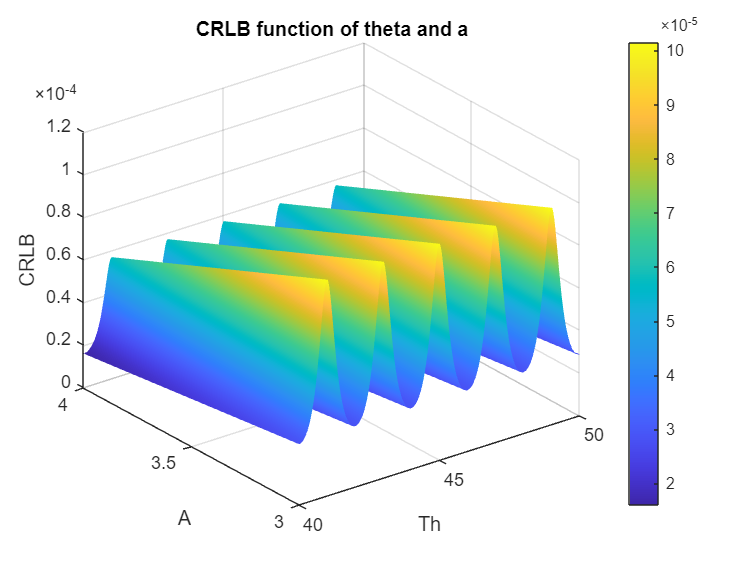

S_r = omega/(2*sqrt(2*log(2))); 

Th= 40:0.01:50;
a_new =3:1:4;

% Preallocating for better performance
stock = zeros(length(Th),length(a_new) );

for j = 1:1:length(a_new)
    for i = 1: 1:length(Th)
        stock(i, j) = cramerrao_a_th(Th(i),a_new(j), N, dx, S_r, S_b);
    end

end

% Plotting the 3D graph
figure;
surf(Th, a_new, stock');
xlabel('Th');
ylabel('A');
zlabel('CRLB');
title('CRLB function of theta and a');
colorbar;  % If you want a colorbar to represent the z values
shading interp; % For smoother color transitions
view(3); % Ensure the view is 3D

Q18

mean_value = 0;
theta_ref = 47;
a_ref = 3;
Nr = 100;
Initial_value = [2,38];
theta_estimated = zeros(1,Nr);
a_estimated = zeros(1,Nr);
for i = 1 :1 : Nr
    Signal_noisy = signal_generation(theta_ref,omega,N,a_ref,S_b,dx,I);
    params_estimated= fminsearch(@(Parameter) -likelihood_theta_a(Parameter,S_b,Signal_noisy,omega,dx),Initial_value);
    a_estimated(i)= params_estimated(1);
    theta_estimated(i) = params_estimated(2);

end
mean_theta =mean(theta_estimated)

mean_theta = 47.0004

mean_a =mean(a_estimated)

mean_a = 3.0010

varian_theta =var(theta_estimated)

varian_theta = 8.7252e-05

varian_a = var(a_estimated)

varian_a = 1.6273e-04

function PSF = r(x, theta,S_r)
c = 1/(sqrt(2*pi)*S_r);
PSF = c*exp(-(((x-theta)^2)/(2*(S_r^2))));
end

% Function calculation the Cramer-Rao lower bound
function a = cramerrao(theta, N, dx,S_r,S_b)
a = 0;
for j = 0: N-1
    A = r(j*dx,theta,S_r);
    B = r((j+1)*dx,theta,S_r);
    a =a+((A-B)^2);
end
a =(S_b^2)/a;
end

% CRLB Function of \theta and a 
% Function calculation the Cramer-Rao lower bound
function a = cramerrao_a_th(theta, a, N, dx,S_r,S_b)
sum_constan= 0;
for j = 0: N-1
    A = r(j*dx,theta,S_r);
    B = r((j+1)*dx,theta,S_r);
    sum_constan =sum_constan+((A-B)^2);
end
a =(S_b^2/a^2)/sum_constan;
end

Q7 generate the noisy signal s_i


% Generate the noisy signal si
function [s] = signal_generation(th,w,N,a,s_b,dx,I)
    A = ((I+1).*dx-th)/(w/(sqrt(log(8))));
    B =  (I.*dx-th)/(w/(sqrt(log(8))));
    r = 0.5.*(erf(A)-erf(B));
    b = s_b.*randn(1,N);
    s = a.*r +b;
end

test the signal generation function 

function [r_i] = no_noisy_signal(th,w,I,dx)
    A = ((I+1).*dx-th)/(w/(sqrt(log(8))));
    B =  (I.*dx-th)/(w/(sqrt(log(8))));
    r_i = 0.5.*(erf(A)-erf(B));
end

Add the log-likelihood function 

function l = likelihood(theta,a,s_b,sigla_noisy,w,dx)
    N = length(sigla_noisy);
    I =linspace(0,N-1,N);
    non_noisy =no_noisy_signal(theta,w,I,dx);
    l = -N*log(sqrt(2*pi)*s_b)-(1/(2*s_b^2))*sum((sigla_noisy-a*non_noisy).^2);
end

function l = likelihood_theta_a(params, s_b, sigla_noisy, w, dx)
    % Extract parameters from the input vector
    a = params(1);
    theta = params(2);
    % Rest of your function remains the same
    N = length(sigla_noisy);
    I = linspace(0, N-1, N);
    non_noisy = no_noisy_signal(theta, w, I, dx);
    l = -N*log(sqrt(2*pi)*s_b) - (1/(2*s_b^2)) * sum((sigla_noisy - a*non_noisy).^2);
end


the CRLB function of W

% Function calculation the Cramer-Rao lower bound
function a = cramerrao_w(theta, N, dx,w,S_b)
a = 0;
s_r = w/(2*sqrt(2*log(2)));
for j = 0: N-1
    A = r(j*dx,theta,s_r);
    B = r((j+1)*dx,theta,s_r);
    a =a+((A-B)^2);
end
a =(S_b^2)/a;
end